# ICA component analysis of LFP and finding the generators 

% reading the data for further analysis 
clear all; close all; clc
% the folder to the data files 
cd('/Volumes/MacBack/GenzpeakelLab/CSD/HPC_32by3601_data')
% the aim of this step is read one data file (example) --> extract the channels
DataChannels        = load('GC_ratID210_veh.mat'); % enter the file name 
% that was my vehicle example GC_ratID210_veh.mat
% the fields name of the sturcture provided 
structure_Name      = fieldnames(DataChannels);
% time vector 
timevect            = linspace(-3,3,3601);
pyramidalChannel    = 8;
HH                  = 'False';
timeFrame           = 90; % equivalent to 150 ms before and after event
idxS                = (timeFrame*2)+1;
timevect1           = linspace(-0.15,0.15,idxS);
% lopping through different events and structures 
for iStr = 1:size(structure_Name,1)-1
    Events_extr = DataChannels.(structure_Name{iStr});% extract different events
    if iStr == 1
        % we extract the events of complex sharp wave events 
        SingleEvents1                           = Events_extr.waveforms;
        EventsTable1                            = Events_extr.grouped_oscil_table;
%         idx_end1                                = EventsTable1.Six_End;
        idx_end1                                = ones(size(SingleEvents1,1),1)*1800;
        for iSingEvent1 = 1:size(SingleEvents1,1)
            twin1                               = [idx_end1(iSingEvent1)-timeFrame idx_end1(iSingEvent1)+timeFrame];
            csd_trial_1                         = csd_analysis_cannabis_single(SingleEvents1{iSingEvent1}, timevect1, HH,pyramidalChannel,twin1);
            csd_mat_cSWR(:,:,iSingEvent1)       = csd_trial_1.data;
            lfp1                                = SingleEvents1{iSingEvent1};
            lfp_mat_cSWR(:,:,iSingEvent1)       = lfp1(:,twin1(1):twin1(2));
        end
    end
    if iStr == 2
        % we extract the events of ripple without sharp waves  
        SingleEvents2                           = Events_extr.waveforms;
        EventsTable2                            = Events_extr.grouped_oscil_table;
%         idx_end2                                = EventsTable2.Six_End;
        idx_end2                                = ones(size(SingleEvents2,1),1)*1800;
        for iSingEvent2 = 1:size(SingleEvents2,1)
            twin2                               = [idx_end2(iSingEvent2)-timeFrame  idx_end2(iSingEvent2)+timeFrame];
            csd_trial_2                         = csd_analysis_cannabis_single(SingleEvents2{iSingEvent2}, timevect1, HH,pyramidalChannel,twin2);
            csd_mat_Ripp(:,:,iSingEvent2)       = csd_trial_2.data;
            lfp2                                = SingleEvents2{iSingEvent2};
            lfp_mat_Ripp(:,:,iSingEvent2)       = lfp2(:,twin2(1):twin2(2));
        end
    end
    if iStr == 3
        % we extract the events of ripple without sharp waves  
        SingleEvents3                           = Events_extr.waveforms;
        EventsTable3                            = Events_extr.grouped_oscil_table;
%         idx_end3                                = EventsTable3.Six_End;
        idx_end3                                = ones(size(SingleEvents3,1),1)*1800;
        for iSingEvent3 = 1:size(SingleEvents3,1)
            twin3                               = [idx_end3(iSingEvent3)-timeFrame  idx_end3(iSingEvent3)+timeFrame];
            csd_trial_3                         = csd_analysis_cannabis_single(SingleEvents3{iSingEvent3}, timevect1, HH,pyramidalChannel,twin3);
            csd_mat_SW(:,:,iSingEvent3)         = csd_trial_3.data;
            lfp3                                = SingleEvents3{iSingEvent3};
            lfp_mat_SW(:,:,iSingEvent3)         = lfp3(:,twin3(1):twin3(2));
        end
    end
    if iStr == 4
        % we extract the events of ripple without sharp waves  
        SingleEvents4                           = Events_extr.waveforms;
        EventsTable4                            = Events_extr.grouped_oscil_table;
%         idx_end4                                = EventsTable4.Six_End;
        idx_end4                                = ones(size(SingleEvents4,1),1)*1800;
        for iSingEvent4 = 1:size(SingleEvents4,1)
            twin4                               = [idx_end4(iSingEvent4)-timeFrame  idx_end4(iSingEvent4)+timeFrame];
            csd_trial_4                         = csd_analysis_cannabis_single(SingleEvents4{iSingEvent4}, timevect1, HH,pyramidalChannel,twin4);
            csd_mat_SWR(:,:,iSingEvent4)        = csd_trial_4.data;
            lfp4                                = SingleEvents4{iSingEvent4};
            lfp_mat_SWR(:,:,iSingEvent4)        = lfp4(:,twin4(1):twin4(2));
        end
    end
end
disp('Finished')

Finished


% first reading and understanding the data as reported Makarov 
% First working on the lfp recordings 
% Reading and plotting the LFP recordings 

clear all; close all; clc

dum = load('e8_6HzA15.txt')';

Error using load
'e8_6HzA15.txt' is not found in the current folder
or on the MATLAB path, but exists in:
    /Users/abdelrahmanrayan/Documents/MATLAB/ICA_LFP

Change the MATLAB current folder or add its folder
to the MATLAB path.

LFP = dum(2:end,:);
Fs = 1/(dum(1,2)-dum(1,1));
id1 = round(1.9*Fs); id2 = round(2.9*Fs);
figure('color','w','position',[100 100 1200 700])
subplot('position',[0.05 0.55 0.35 0.4])
for k = 1:size(LFP,1),
    plot((id1:id2)/Fs,LFP(k,id1:id2) - 0.5*(k-1),'k','LineWidth',2)
    hold on
end
axis([[id1, id2]/Fs,-size(LFP,1)*0.5,0.5])
axis off
title('raw LFPs','FontSize',14)

% computing the principle components and ICAs of the LFP signal 
% the outcome of this analysis is the spatial weights of the LFP
[~,~,D] = princomp(LFP');

Unrecognized function or variable 'LFP'.

N=find(cumsum(D)/sum(D)>0.99,1);
[weights,sphere,compvars,bias,signs,lrates,v] = ...
    runica(LFP,'verbose','off','pca',N,'maxsteps',1500);
M=pinv(weights*sphere);
M(:,2)=-M(:,2); v(2,:)=-v(2,:);
[nE, nG] = size(M);
alpha = max(M);
for k = 1:nG,
    M(:,k)=M(:,k)/alpha(k);
    v(k,:)=alpha(k)*v(k,:);
end
s=std(v,[],2);
[~,idx]=sort(s,'descend');
M=M(:,idx);
v=v(idx,:);
subplot('position',[0.45 0.57 0.1 0.36])
xx=1:0.25:nE;
clr='bgrcmyk';
smb='osv*+x';
plot([0 0],[1 nE],'k--','LineWidth',2)
hold on
for k = 1:nG,
    plot(spline(1:nE,M(:,k),xx),xx,[clr(k) '-'],'LineWidth',2)
    plot(M(:,k),1:nE,[clr(k) smb(k)],'LineWidth',2,'MarkerSize',8,'MarkerFaceColor','w')
end
set(gca,'YDir','reverse')
axis([-1 1 1 nE])
set(gca,'FontSize',12)
title('spatial weights','FontSize',14)

% plotting the generators --> the number of the principle components 
subplot('position',[0.6 0.6 0.35 0.3])
for k = 1:nG,
    plot((id1:id2)/Fs,v(k,id1:id2)-(k-1),clr(k),'LineWidth',2)
    hold on
end
title('time courses','FontSize',14)
axis([[id1,id2]/Fs,-nG,1])
axis off
legend({'G1','G2'},'location','best','FontSize',12)

% computing the CSD for all the LFP signal 
subplot('position',[0.05 0.1 0.4 0.35])
CSD = diff(LFP(:,id1:id2),2);
cL = linspace(-0.12,0.12,10);
contourf((id1:id2)/Fs,2:nE-1,CSD,cL,'LineColor','none')
set(gca,'YDir','reverse')
set(gca,'FontSize',12)
colormap(flipud(redblue))
colorbar
xlabel('time (s)','FontSize',14)
title('CSD of raw LFPs','FontSize',14)

% Now computing the CSD based on the generators
subplot('position',[0.6 0.1 0.35 0.35])
LFP_G1=M(:,1)*v(1,:);
CSD_G1=diff(LFP_G1(:,id1:id2),2);
contourf((id1:id2)/Fs, 2:nE-1,CSD_G1,cL,'LineColor','none')
set(gca,'YDir','reverse')
set(gca,'FontSize',12)
xlabel('time (s)','FontSize',14)
title('CSD of virtual LFPs generated by G1','FontSize',14)

% Now trying the the real data example 
Fs                  = 600;
lfpExample          = lfp_mat_cSWR(:,:,3);
% filtering the signal 
order               = 3;
nyquist             = Fs/2;
passband = [30 200]

passband =     30   200


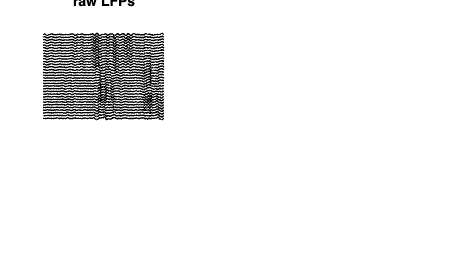

[b a] = butter(order,[passband(1)/nyquist passband(2)/nyquist],'bandpass');
for iCh = 1:32
    filtered(iCh,:) = filtfilt(b,a,lfpExample(iCh,:));
end
temp_sm = 11;
% temporal smoothing 
for ch = 1:size(filtered,1) 
    lfp_frag(ch,:) = smooth(filtered(ch,:),temp_sm,'sgolay');
end
spat_sm = 11; 
% spatial smoothing 
for t = 1:size(filtered,2) 
    lfp_frag(:,t) = smooth(filtered(:,t),spat_sm,'lowess');
end

lfpExample = lfp_frag;
timeview            = [-0.1 0.1];
figure('color','w','position',[100 100 1200 700])
subplot('position',[0.05 0.55 0.35 0.4])
for ch=1:size(lfpExample,1)
    sh_tmp = bz_NormToRange(lfpExample(ch,:), [ch+0.5 ch-0.5]);
    plot(timevect1,sh_tmp,'k','LineWidth',1.5); hold on;
    clear sh_tmp
end
axis off
title('raw LFPs','FontSize',14)

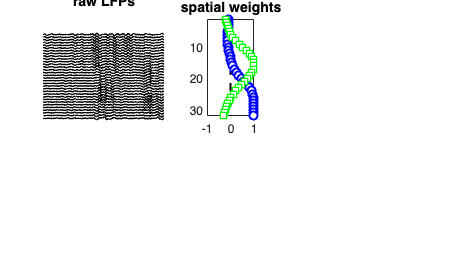

% computing the principle components and ICAs of the real LFP signal
% the outcome of this analysis is the spatial weights of the LFP
[~,~,D] = princomp(lfpExample');
N=find(cumsum(D)/sum(D)>0.90,1);
[weights,sphere,compvars,bias,signs,lrates,v] = ...
    runica(lfpExample,'verbose','off','pca',N,'maxsteps',1500);
M=pinv(weights*sphere);
% M(:,2)=-M(:,2); v(2,:)=-v(2,:);
[nE, nG] = size(M);
alpha = max(M);
for k = 1:nG,
    M(:,k)=M(:,k)/alpha(k);
    v(k,:)=alpha(k)*v(k,:);
end
s=std(v,[],2);
[~,idx]=sort(s,'descend');
M=M(:,idx);
v=v(idx,:);
subplot('position',[0.45 0.57 0.1 0.36])
xx=1:0.25:nE;
clr='bgrcmyk';
smb='osv*+x';
plot([0 0],[1 nE],'k--','LineWidth',2)
hold on
for k = 1:nG,
    plot(spline(1:nE,M(:,k),xx),xx,[clr(k) '-'],'LineWidth',2)
    plot(M(:,k),1:nE,[clr(k) smb(k)],'LineWidth',2,'MarkerSize',8,'MarkerFaceColor','w')
end
set(gca,'YDir','reverse')
axis([-1 1 1 nE])
set(gca,'FontSize',12)
title('spatial weights','FontSize',14)

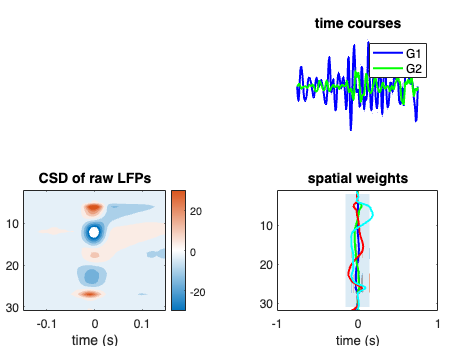

% pltotting a new figure for the second spatial derivative of the spatial
% weights 
figure(3)
for k = 1:nG
    hold on
    M2 = diff(M(:,k),2);
    plot(spline(1:numel(M2),M2,xx),xx,[clr(k) '-'],'LineWidth',2)
end
set(gca,'YDir','reverse')
axis([-0.5 0.5 1 nE])
set(gca,'FontSize',12)
title('Second derivative of the spatial weights','FontSize',14)

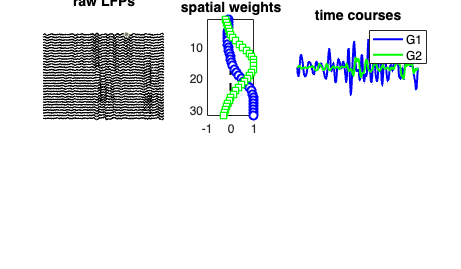

% plotting the generators --> the number of the principle components 
subplot('position',[0.6 0.6 0.35 0.3])
for k = 1:nG,
    plot(timevect1,v(k,:)-(k-1),clr(k),'LineWidth',2)
    hold on
end
title('time courses','FontSize',14)
axis off
legend({'G1','G2','G3','G4'},'location','best','FontSize',12)

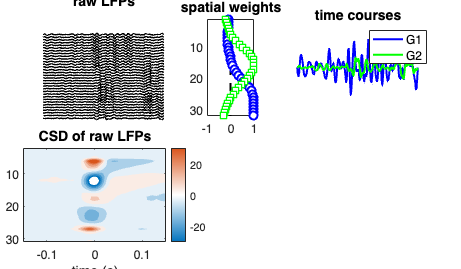

% computing the CSD for all the LFP signal 
subplot('position',[0.05 0.1 0.4 0.35])
CSD = csd_mat_cSWR(:,:,3);% diff(lfpExample,2,2);
cL = linspace(-30,30,10);
contourf(timevect1,2:nE-1,mean(csd_mat_SW,3)',cL,'LineColor','none')
set(gca,'YDir','reverse')
set(gca,'FontSize',12)
colormap(flipud(redblue))
colorbar
xlabel('time (s)','FontSize',14)
title('CSD of raw LFPs','FontSize',14)

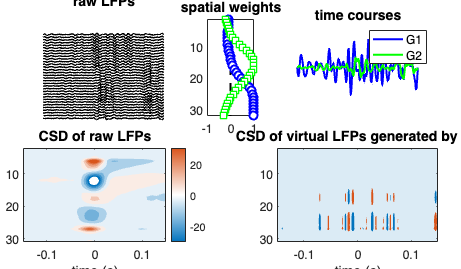

% Now computing the CSD based on the generators
subplot('position',[0.6 0.1 0.35 0.35])

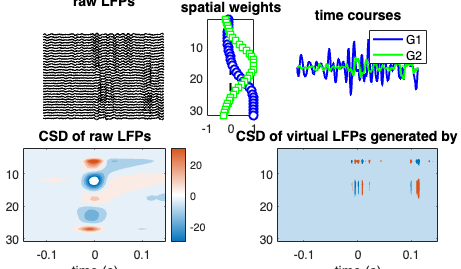

LFP_G1=M(:,2)*v(2,:);
CSD_G1=diff(LFP_G1(:,:),2);
contourf(timevect1, 2:nE-1,CSD_G1,cL,'LineColor','none')
set(gca,'YDir','reverse')
set(gca,'FontSize',12)
xlabel('time (s)','FontSize',14)
title('CSD of virtual LFPs generated by G1','FontSize',14)

## Making some tests according to my readings (see Notion notebook for further details)

% computing the second derivative of each component
figure(2)
clf
subplot(1,2,1)
plot([0 0],[1 nE],'k--','LineWidth',2)
hold on 
for k = 1:nG,
    plot(spline(1:nE,M(:,k),xx),xx,[clr(k) '-'],'LineWidth',2)
    plot(M(:,k),1:nE,[clr(k) smb(k)],'LineWidth',2,'MarkerSize',8,'MarkerFaceColor','w')
end
set(gca,'YDir','reverse')
axis([-1 1 1 nE])
set(gca,'FontSize',12)
title('voltage loading','FontSize',14)

% calculate the CSD of different spatial components 
subplot(1,2,2)
hold on
for k = 1:nG,
    plot(spline(1:30,diff(M(:,k),2),xx),xx,[clr(k) '-'],'LineWidth',2)
    plot(diff(M(:,k),2),1:30,[clr(k) smb(k)],'LineWidth',2,'MarkerSize',8,'MarkerFaceColor','w')
end
set(gca,'YDir','reverse')
axis([-1 1 1 nE])
set(gca,'FontSize',12)
title('CSD','FontSize',14)

## Doing systematic analysis of the ICA related analysis --> first I want to compoare the cSWR and Ripple activity to see any differences 

% first choose an example data before you start running the analysis 
Fs                  = 600;
lfpExample          = lfp_mat_Ripp(1:20,:,3);
% lfpExFilter         = bz_Filter(lfpExample','passband',[30 300],'order',4,'filter','butter')';
timeview            = [-0.1 0.1];
clf
figure('color','w','position',[100 100 1200 700])
subplot('position',[0.05 0.55 0.35 0.4])
for ch=1:size(lfpExample,1)
    sh_tmp = bz_NormToRange(lfpExample(ch,:), [ch+0.5 ch-0.5]);
    plot(timevect1, sh_tmp,'k','LineWidth',1.5); hold on;
    clear sh_tmp
end
axis off
xlim(timeview)
title('raw LFPs','FontSize',14)

[~,~,D] = princomp(lfpExample');
N=find(cumsum(D)/sum(D)>0.99,1);
[weights,sphere,compvars,bias,signs,lrates,v] = ...
    runica(lfpExample,'verbose','off','pca',N,'maxsteps',1500);
M=pinv(weights*sphere);
M(:,2)=-M(:,2); v(2,:)=-v(2,:);
[nE, nG] = size(M);
alpha = max(M);
for k = 1:nG,
    M(:,k)=M(:,k)/alpha(k);
    v(k,:)=alpha(k)*v(k,:);
end
s=std(v,[],2);
[~,idx]=sort(s,'descend');
M=M(:,idx);
v=v(idx,:);
subplot('position',[0.45 0.57 0.1 0.36])
xx=1:0.25:nE;
clr='bgrcmyk';
smb='osv*+x';
plot([0 0],[1 nE],'k--','LineWidth',2)
hold on
for k = 1:nG,
    plot(spline(1:nE,M(:,k),xx),xx,[clr(k) '-'],'LineWidth',2)
    plot(M(:,k),1:nE,[clr(k) smb(k)],'LineWidth',2,'MarkerSize',8,'MarkerFaceColor','w')
end
set(gca,'YDir','reverse')
axis([-1 1 1 nE])
set(gca,'FontSize',12)
title('spatial weights','FontSize',14)

% plotting the generators --> the number of the principle components 
subplot('position',[0.6 0.6 0.35 0.3])
for k = 1:nG,
    plot(timevect1, v(k,:)-(k-1),clr(k),'LineWidth',2)
    hold on
end
title('time courses','FontSize',14)
xlim(timeview)
axis off
legend({'G1','G2','G3','G4'},'location','best','FontSize',12)

% computing the CSD for all the LFP signal 
subplot('position',[0.05 0.1 0.4 0.35])
CSD = diff(lfpExample,2);
cL = linspace(-30,30,10);
contourf(timevect1,1:nE,csd_mat_Ripp(:,1:20,3)',cL,'LineColor','none')
set(gca,'YDir','reverse')
set(gca,'FontSize',12)
colormap(flipud(redblue))
colorbar
xlim(timeview)
xlabel('time (s)','FontSize',14)
title('CSD of raw LFPs','FontSize',14)

% Now computing the CSD based on the generators
subplot('position',[0.6 0.1 0.35 0.35])
LFP_G1=M(:,3)*v(3,:);
CSD_G1=csd_analysis_cannabis_single(LFP_G1, timevect2, HH,pyramidalChannel,[1 601]);;
contourf(timevect1, 2:nE-1,CSD_G1.data',cL,'LineColor','none')
set(gca,'YDir','reverse')
set(gca,'FontSize',12)
xlim(timeview)
colorbar
xlabel('time (s)','FontSize',14)
title('CSD of virtual LFPs generated by G1','FontSize',14)

## Run systematic analysis on each type to examine the voltage loading (spatial weights) and how they differ 

% doing the analysis for the complex sharp wave ripples 
for icSWRL= 1:size(lfp_mat_cSWR,3)
    lfpData             = lfp_mat_Ripp(1:20,:,icSWRL); % 1-20 restricts the analysis to the CA1
    [~,~,D]             = princomp(lfpData');
    N                   =find(cumsum(D)/sum(D)>0.8,1);
    [weights,sphere,compvars,bias,signs,lrates,v] = ...
        runica(lfpData,'verbose','off','pca',N,'maxsteps',1500);
    M                   =pinv(weights*sphere);
%     M(:,2)              =-M(:,2); 
%     v(2,:)              =-v(2,:);
    [nE, nG]            = size(M);
    alpha               = max(M);
    for k = 1:nG,
        M(:,k)          = M(:,k)/alpha(k);
        v(k,:)          = alpha(k)*v(k,:);
    end
    s                   = std(v,[],2);
    [~,idx]             = sort(s,'descend');
    M                   = M(:,idx);
    v                   = v(idx,:);
    xx                  = 1:0.1:nE;

    for k = 1:nG,
        if k == 1
            spatial1(:,icSWRL)      = spline(1:nE,M(:,k),xx);
            temporal1(:,icSWRL)     = v(k,:)-(k-1);
        end
        if k == 2
            spatial2(:,icSWRL)      = spline(1:nE,M(:,k),xx);
            temporal2(:,icSWRL)     = v(k,:)-(k-1);
        end
        if k == 3
           spatial3(:,icSWRL)       = spline(1:nE,M(:,k),xx); 
           temporal3(:,icSWRL)     = v(k,:)-(k-1);
        end
    end

end

% plotting the sptail components separately 
clf;
fig1 = figure(1);
fig1.Renderer='Painters'

fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [384 258 512 384]
       Units: 'pixels'

  Show all properties


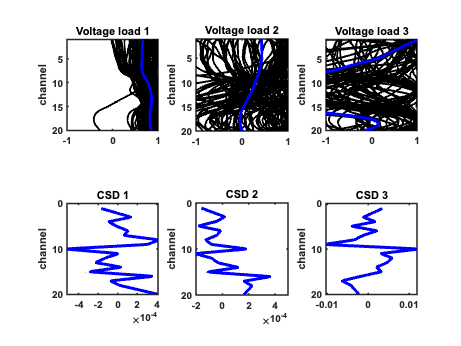

subplot(2,3,1)
plot(spatial1',xx,'k-','LineWidth',2)
hold on
plot(mean(spatial1,2),xx,'b-','LineWidth',3)
set(gca,'YDir','reverse');ylabel('channel');title('Voltage load 1');
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
set(gcf, 'Color','w')
axis square
axis([-1 1 1 nE])
subplot(2,3,2)
plot(spatial2',xx,'k-','LineWidth',2)
hold on
plot(mean(spatial2,2),xx,'b-','LineWidth',3)
set(gca,'YDir','reverse');ylabel('channel');title('Voltage load 2');
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
set(gcf, 'Color','w')
axis square
axis([-1 1 1 nE])
subplot(2,3,3)
plot(spatial3',xx,'k-','LineWidth',2)
hold on
plot(mean(spatial3,2),xx,'b-','LineWidth',3)
set(gca,'YDir','reverse');ylabel('channel');title('Voltage load 3');
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
set(gcf, 'Color','w')
axis square
axis([-1 1 1 nE])
subplot(2,3,4)
plot(diff(mean(spatial1,2),2),xx(2:end-1),'b-','LineWidth',3)
set(gca,'YDir','reverse');ylabel('channel');title('CSD 1');
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
set(gcf, 'Color','w')
axis square
subplot(2,3,5)
plot(diff(mean(spatial2,2),2),xx(2:end-1),'b-','LineWidth',3)
set(gca,'YDir','reverse');ylabel('channel');title('CSD 2');
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
set(gcf, 'Color','w')
axis square
subplot(2,3,6)
plot(diff(mean(spatial3,2),2),xx(2:end-1),'b-','LineWidth',3)
set(gca,'YDir','reverse');ylabel('channel');title('CSD 3');
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
set(gcf, 'Color','w')
axis square

% plotting the temporal resolution of each signal 
clf;
fig1 = figure(2);
fig1.Renderer='Painters'

fig1 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [384 258 512 384]
       Units: 'pixels'

  Show all properties


plot(timevect1,temporal1','k-','LineWidth',2)

Unrecognized function or variable 'temporal1'.

hold on
plot(timevect1,mean(temporal1,2),'b-','LineWidth',4)
set(gca,'YDir','reverse');ylabel('channel');title('Voltage load 1');
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
set(gcf, 'Color','w')
axis square
axis off

% running a systematic analysis of the ICA components ---> all channels
% analysis 
% I will start with examining the power spectrum of each event and csd
% event
winsize                 = 60;                      % Equivalent to 2s
overlap                 = 30;                      % Equivalent to 50% of the window
nfft                    = 2^nextpow2(winsize);
clear powerSpec
for icSWRL= 1:size(csd_mat_cSWR,3)
    lfpData             = csd_mat_cSWR(:,:,icSWRL); % 1-20 restricts the analysis to the CA1
    for i = 1:30
        [powerSpec(i,:,icSWRL),F2]       = pwelch(lfpData(:,i),winsize,overlap,nfft,600);
    end
end

## Understanding different parts of the analysis and trying different combinations of methods

**Tuesday 31.01**

**Examining all the components of the channels and comparing it to the PCA guided components analysis **

clr                 ='bgrcmyk';
smb                 ='osv*+x';
icSWRL              = 1;
lfpData             = lfp_mat_Ripp(:,:,icSWRL); % 1-20 restricts the analysis to the CA1
[~,~,D]             = princomp(lfpData');
N                   =find(cumsum(D)/sum(D)>0.80,1);
[weights,sphere,compvars,bias,signs,lrates,v] = ...
    runica(lfpData,'verbose','off','pca',32,'maxsteps',1500);
M                   =pinv(weights*sphere);
[nE, nG]            = size(M);
alpha               = max(M);
for k = 1:nG,
    M(:,k)          = M(:,k)/alpha(k);
    v(k,:)          = alpha(k)*v(k,:);
end
s                   = std(v,[],2);
[~,idx]             = sort(s,'descend');
M                   = M(:,idx);
v                   = v(idx,:);
xx                  = 1:0.1:nE;
clear spatial1 temporal1
for k = 1:nG,
    spatial1(:,k,icSWRL)      = spline(1:nE,M(:,k),xx);
    temporal1(:,k,icSWRL)     = v(k,:)-(k-1);
end

% plotting the figures of the spatial weights
clf
fig1 = figure(1);
fig1.Renderer='Painters'

fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [384 258 512 384]
       Units: 'pixels'

  Show all properties


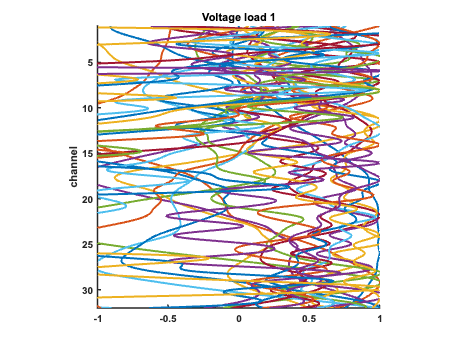

for ip = 1:size(spatial1,2)
    hold all
%     plot(spatial1(:,ip,1)',xx,[clr(ip) '-'],'LineWidth',2)
    plot(spatial1(:,ip,1)',xx,'LineWidth',2)
end
% legend('G1','G2','G3','G4','Location','Best')
set(gca,'YDir','reverse');ylabel('channel');title('Voltage load 1');
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
set(gcf, 'Color','w')
axis([-1 1 1 32])
axis square

% I wil start the analysis by only focusing on two generators to understand
% their contribution to different ripple types 
clear NumG
for icSWRL= 1:size(lfp_mat_SWR,3)
    lfpData             = lfp_mat_SWR(:,:,icSWRL); % 1-20 restricts the analysis to the CA1
    [~,~,D]             = princomp(lfpData');
    N                   =find(cumsum(D)/sum(D)>0.80,1);
    [weights,sphere,compvars,bias,signs,lrates,v] = ...
        runica(lfpData,'verbose','off','pca',N,'maxsteps',1500);
    M                   =pinv(weights*sphere);
    [nE, nG]            = size(M);
    alpha               = max(M);
    % examine the number of generators for each event
    NumG(1,icSWRL)      = nG;
%     for k = 1:nG,
%         M(:,k)          = M(:,k)/alpha(k);
%         v(k,:)          = alpha(k)*v(k,:);
%     end
%     s                   = std(v,[],2);
%     [~,idx]             = sort(s,'descend');
%     M                   = M(:,idx);
%     M                    = v(idx,:);
%     for k = 1:nG,
%         spatial1(:,k,icSWRL)      = M(:,k);
%         temporal1(:,k,icSWRL)     = v(k,:)-(k-1);
%     end
end

% run analysis to get the spatial weights of different electrodes 
for icSWRL= 1:size(lfp_mat_SWR,3)
    lfpData             = lfp_mat_SWR(:,:,icSWRL); % 1-20 restricts the analysis to the CA1
    [~,~,D]             = princomp(lfpData');
    N                   =find(cumsum(D)/sum(D)>0.80,1);
    [weights,sphere,compvars,bias,signs,lrates,v] = ...
        runica(lfpData,'verbose','off','pca',N,'maxsteps',1500);
    M                   =pinv(weights*sphere);
    [nE, nG]            = size(M);
    alpha               = max(M);
    % examine the number of generators for each event
    NumG(1,icSWRL)      = nG;
end